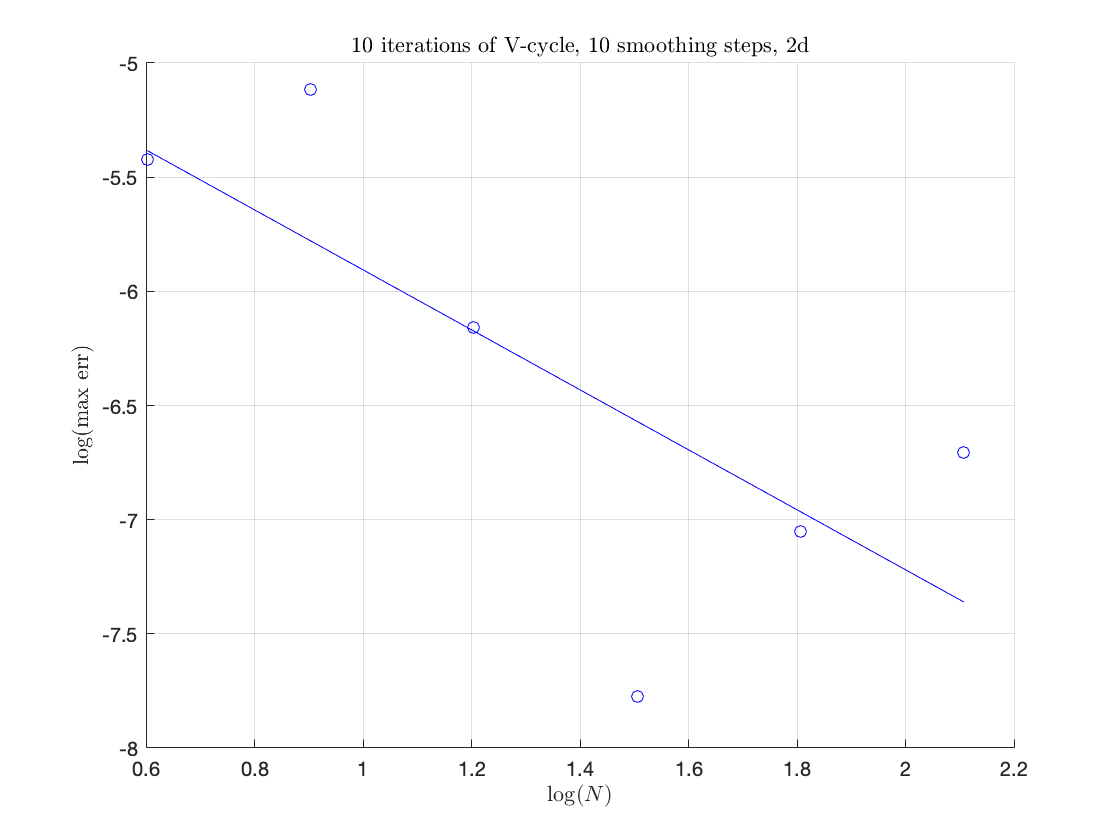

err_decay_rate =    1.313547251325079


Ns = [4,8,16,32,64,128];
hs = 2./Ns;
errs2g = [3.780225234799664e-06, 7.660427441774295e-06, 6.949355670531673e-07, 1.675300168231010e-08, 8.831981905890740e-08, 1.977357039946448e-07];
Ns2 = [8, 16, 32, 64, 128];
errsvc = [     7.630632276569432e-06     3.780225234799664e-06,      1.654591327889129e-08,      5.647538641601058e-09,      8.864943288125482e-09];
plotfun(Ns,errs2g)

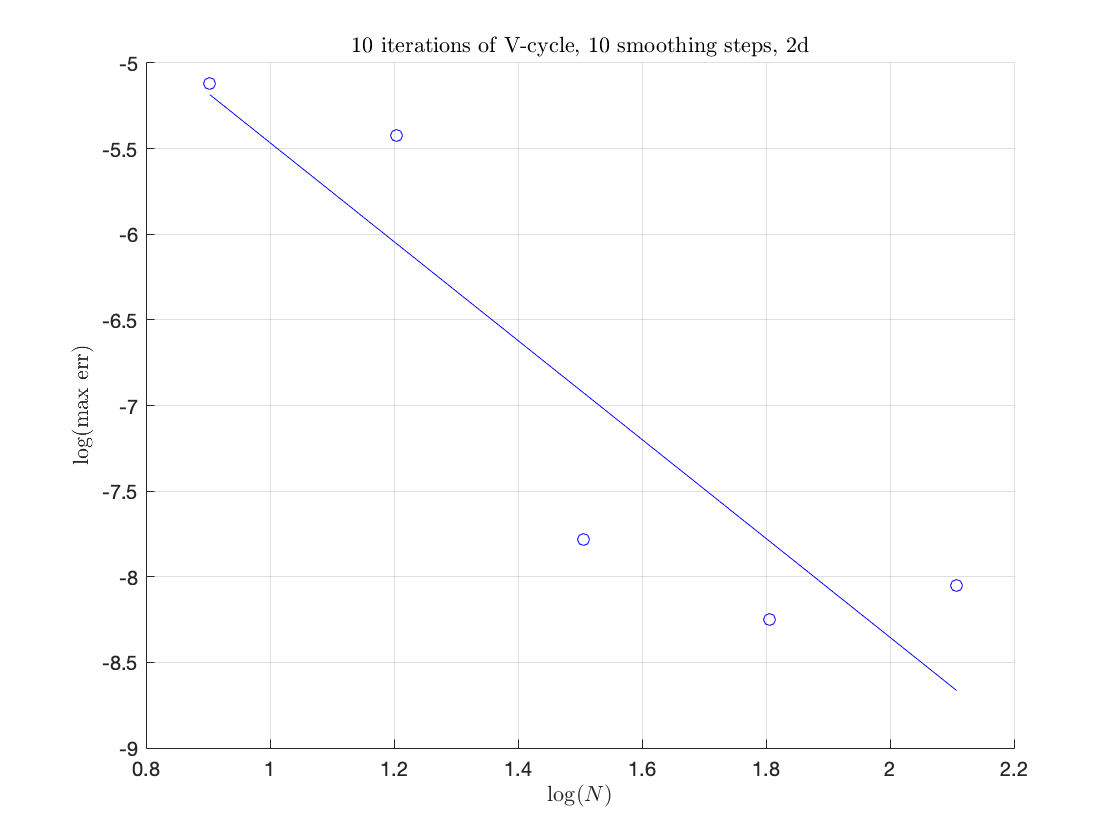

err_decay_rate =    2.888558521813050


plotfun(Ns2,errsvc)

function [] = plotfun(Ns,es)
    figure
    hold on

    Bp_es = polyfit(log10(Ns), log10(es), 1);
    Yp_es = polyval(Bp_es,log10(Ns));
    
    plot(log10(Ns), log10(es), 'ob')
    
    title(sprintf('10 iterations of V-cycle, 10 smoothing steps, 2d'), 'interpreter', 'latex')
    xlabel('$\log(N)$', 'interpreter', 'latex')
    ylabel('$\log$(max err)', 'interpreter', 'latex')
    
    plot(log10(Ns), Yp_es, '-b')
    hold off
    grid
    err_decay_rate = -Bp_es(1)
end
